% Sobel–Watershed Cell Segmentation
%
% DESCRIPTION:
%   Segments cell images using a Sobel-based edge detector combined with a
%   marker-controlled watershed transform. Supports batch processing via a
%   file browser and handles both bright-field and dark-field microscopy
%   images.
%
%   Pipeline:
%     1. Gaussian smoothing        — reduces noise before edge detection.
%     2. Sobel edge detection      — computes gradient magnitude; both steps
%                                    performed in the frequency domain via FFT.
%     3. Iterative thresholding    — binarises gradient magnitude by
%                                    converging on an optimal threshold.
%     4. Foreground detection      — adaptive Otsu thresholding isolates
%                                    cell regions from background.
%     5. Marker extraction         — distance transform followed by
%                                    morphological open-close by reconstruction
%                                    yields one marker per cell.
%     6. Watershed segmentation    — marker-controlled watershed partitions
%                                    the gradient image into cell basins.
%
% INPUTS (entered interactively at runtime):
%   - Image file(s)  : .tif, .png, or .jpg microscopy images selected via
%                      a file browser. Multiple files can be selected with
%                      Ctrl (Windows/Linux) or Command (macOS).
%   - sigma          : (positive scalar) Standard deviation for Gaussian
%                      smoothing. Larger values blur more aggressively.
%   - diskSize       : (positive integer) Radius of the structuring element
%                      used during marker extraction. Should approximate the
%                      radius of a single cell in pixels.
%   - polarity       : ('b' | 'd') Whether cells appear brighter ('b') or
%                      darker ('d') than the background.
%
% OUTPUTS:
%   - Figure per image showing the original image overlaid with:
%       · Red-tinted regions  — classified as background.
%       · Bright-red lines    — watershed boundaries between cells.
%   - Command Window summary per image:
%       · Number of detected cells.
%       · Mean cell area (pixels).
%   Optional (uncomment lines in the Visualisation section):
%   - PNG overlay image saved alongside the source file.
%   - Binary segmentation mask saved as a TIFF alongside the source file.
%
% PARAMETERS (see 'Configurable Parameters' section below):
%   - CONVERGENCE_TOL      : Threshold convergence tolerance   (default: 1e-5).
%   - ADAPTIVE_SENSITIVITY : Sensitivity for adaptive Otsu     (default: 0.30).
%   - BG_BASIN_THRESHOLD   : Background pixel fraction above which a basin is
%                            classified as background          (default: 0.89).
%   - MARKER_NOISE_PCTILE  : Marker components below this area percentile are
%                            discarded as noise                (default: 5).
%   - MARKER_CLOSE_RADIUS  : Disk radius for final marker closing (default: 2).
%   - OVERLAY_ALPHA        : Opacity of the red background overlay (default: 0.45).
%
% DEPENDENCIES:
%   - Image Processing Toolbox (v25.2)
%
% USAGE:
%   1. Optionally adjust values in the 'Configurable Parameters' section.
%   They were carefully selected and should suit most images though. 
%   2. Run the script.
%   3. Select one or more images in the file browser that appears.
%   4. Enter sigma, diskSize, and polarity when prompted.
%   5. Results are displayed in figures and printed to the Command Window.
%
% AUTHOR: Rustam Toshov
% DATE:   April 2026

clear; clc; close all;

% Uncomment to profile total CPU time:
% t0 = cputime;

## Configurable parameters

% Adjust these values to further tune the segmentation. Best values were
% chosen. 
CONVERGENCE_TOL      = 1e-5;  % Iterative threshold convergence criterion
ADAPTIVE_SENSITIVITY = 0.30;  % Sensitivity for adaptive Otsu foreground detection
BG_BASIN_THRESHOLD   = 0.89;  % Background pixel fraction that classifies a basin as background
MARKER_NOISE_PCTILE  = 5;     % Marker components below this area percentile are treated as noise
MARKER_CLOSE_RADIUS  = 2;     % Disk radius (px) for morphological closing of final markers
OVERLAY_ALPHA        = 0.45;  % Opacity [0, 1] of the red background overlay in output figures

## Import Image(s)

% Hold Ctrl (or Command on Mac) to select multiple images at once.
[fileNames, folderPath] = uigetfile( ...
    {'*.tif;*.png;*.jpg', 'Image Files'}, ...
    'Select one or more images to analyse', ...
    'MultiSelect', 'on');

if isequal(fileNames, 0)
    error('No images selected. Stopping.');
end

% Normalise to cell array so single and multiple selections are handled
% identically throughout the rest of the script.
if ischar(fileNames)
    fileNames = {fileNames};
end

fprintf('Selected %d image(s) to process.\n', numel(fileNames));

Selected 1 image(s) to process.


## User Input: Sigma, Disk Size and Polarity

% Sigma
sigmaPrompt = '';
while true
    sigma = input([sigmaPrompt 'Sigma for Gaussian blur: ']);
    if isnumeric(sigma) && isscalar(sigma) && sigma > 0
        break;
    end
    sigmaPrompt = 'Invalid input. Enter a positive scalar.\n>> ';
end

% Disk Size 
diskPrompt = '';
while true
    diskSize = input([diskPrompt ...
        'Disk size (positive integer; approximate single-cell radius in pixels): ']);
    if isnumeric(diskSize) && isscalar(diskSize) && ...
            diskSize > 0 && mod(diskSize, 1) == 0
        break;
    end
    diskPrompt = 'Invalid input. Enter a positive integer.\n>> ';
end

% Polarity
polarityPrompt = '';
while true
    polarityInput = input( ...
        [polarityPrompt 'Are cells brighter or darker than background? (b/d): '], 's');
    if strcmpi(polarityInput, 'b')
        polarity = 'bright'; break;
    elseif strcmpi(polarityInput, 'd')
        polarity = 'dark';   break;
    end
    polarityPrompt = 'Invalid input. Enter b or d.\n>> ';
end

## Process each image

for imgIdx = 1:numel(fileNames)

    fprintf('\n--- Processing image %d of %d: %s ---\n', ...
        imgIdx, numel(fileNames), fileNames{imgIdx});

    % Read image and convert to grayscale
    I      = imread(fullfile(folderPath, fileNames{imgIdx}));
    Igray  = im2gray(I);
    [M, N] = size(Igray);


--- Processing image 1 of 1: Base_image.tif ---


### Gaussian Smoothing    

    kernelSize  = 2 * ceil(3 * sigma) + 1;      % Using 3-sigma rule
    gaussKernel = fspecial('gaussian', [kernelSize kernelSize], sigma);

    % Zero-pad kernel to image size, then circularly shift its centre to
    % (1,1) so FFT-based convolution introduces no linear phase shift.
    gaussPad = zeros(M, N);
    gaussPad(1:kernelSize, 1:kernelSize) = gaussKernel;
    gaussKernelFFT = fft2(circshift(gaussPad, ...
        [-(floor(kernelSize / 2)), -(floor(kernelSize / 2))]));

### Sobel edge detection in Frequency domain

    % Horizontal and vertical Sobel operators
    sobelX = [-1 0 1; -2 0 2; -1 0 1];
    sobelY = [ 1 2 1;  0 0 0; -1 -2 -1];

    % Zero-pad and centre each kernel at (1,1) for FFT-based convolution
    sobelXPad = zeros(M, N); sobelXPad(1:3, 1:3) = sobelX;
    sobelYPad = zeros(M, N); sobelYPad(1:3, 1:3) = sobelY;

    sobelXFFT = fft2(circshift(sobelXPad, [-1, -1]));
    sobelYFFT = fft2(circshift(sobelYPad, [-1, -1]));

    % Transform image into frequency domain and apply smoothing then Sobel
    imageFFT    = fft2(double(Igray));
    imageSmooth = imageFFT .* gaussKernelFFT;

    % Retain only real parts to discard floating-point imaginary artefacts
    Gx = real(ifft2(imageSmooth .* sobelXFFT));   % Horizontal gradient
    Gy = real(ifft2(imageSmooth .* sobelYFFT));   % Vertical gradient
    G  = sqrt(Gx.^2 + Gy.^2);                    % Gradient magnitude

### Calculate threshold T iteratively

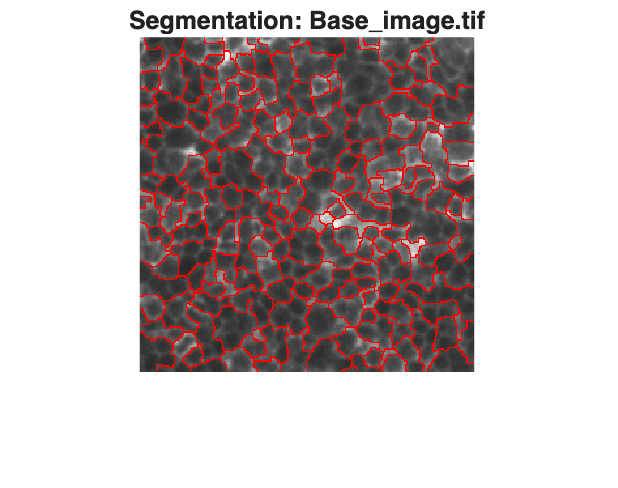

    Gvec = G(:);
    T    = mean(Gvec);   % Initialise threshold as the global mean of the gradient

    while true
        muLow  = mean(Gvec(Gvec <  T));    % Mean of below-threshold pixels
        muHigh = mean(Gvec(Gvec >= T));    % Mean of above-threshold pixels
        T_new  = (muLow + muHigh) / 2;     % New threshold: midpoint of class means

        if abs(T_new - T) < CONVERGENCE_TOL, break; end
        T = T_new;
    end

### Foreground detection

    % Binary edge mask: pixels whose gradient exceeds the converged threshold
    edgeMask = G >= T;

    % Adaptive Otsu thresholding to identify the cell foreground
    foreground = imbinarize(Igray, 'adaptive', ...
        'ForegroundPolarity', polarity, 'Sensitivity', ADAPTIVE_SENSITIVITY);

    % Opening-by-reconstruction: erode then reconstruct to remove small
    % speckle noise without shrinking genuine foreground regions
    foreground = imreconstruct(imerode(foreground, strel('disk', 1)), foreground);


  Cells detected:  192


  Mean cell area:  296.0 px



    % Closing-by-reconstruction: fills small holes inside foreground objects
    % by reconstructing from a dilated complement, then complementing back

All images processed.


    ForeDil    = imdilate(foreground, strel('disk', 1));
    foreground = imcomplement( ...
        imreconstruct(imcomplement(ForeDil), imcomplement(foreground)));

### Marker creation

    % Confine watershed basins to the foreground
    edgeMask = edgeMask | ~foreground;

    % Distance transform from the combined edge mask
    D  = bwdist(edgeMask);
    se = strel('disk', diskSize);

    % Open-by-reconstruction: removes ridges narrower than diskSize,
    % leaving flat plateaus inside each cell
    D_opened = imreconstruct(imerode(D, se), D);

    % Close-by-reconstruction on the complement: merges nearby plateaus
    % so each cell contributes exactly one regional maximum
    D_closed = imreconstruct( ...
        imcomplement(imdilate(D_opened, se)), imcomplement(D_opened));
    D_final  = imcomplement(D_closed);

    % Extract regional maxima as seed markers
    markers = imregionalmax(D_final);

    % Discard the smallest marker components (likely imaging noise)
    markerProps   = regionprops(markers, 'Area');
    minMarkerArea = prctile([markerProps.Area], MARKER_NOISE_PCTILE);
    markers       = bwareaopen(markers, round(minMarkerArea));

    % Fill and close remaining markers to guarantee one solid seed per cell
    markers = imfill(imclose(markers, strel('disk', MARKER_CLOSE_RADIUS)), 'holes');

### Watershed segmentation

    % Impose gradient minima at marker locations so watershed boundaries
    % always form between cells rather than inside them
    G_imposed = imimposemin(G, markers);

    % Watershed transform; label 0 = boundary pixels, labels >= 1 = basins
    W = watershed(G_imposed);

### Background classification

    % For each basin, compute the fraction of its pixels that fall outside
    % the foreground mask. Basins exceeding 0.89 are background.
    boundaries  = (W == 0);
    basinLabels = unique(W(W > 0));
    maxLabel    = max(basinLabels);

    % Vectorised basin statistics via accumarray (avoids per-basin loop)
    basinPixelCount = accumarray(W(W > 0),               1, [maxLabel, 1]);
    bgPixelCount    = accumarray(W(~foreground & W > 0), 1, [maxLabel, 1]);
    bgFraction      = bgPixelCount ./ max(basinPixelCount, 1);   % Guard against divide-by-zero
    isBackground    = bgFraction > BG_BASIN_THRESHOLD;
    bgMask          = ismember(W, find(isBackground));

### Visualisation

    % Convert grayscale to RGB so coloured overlays can be applied
    Irgb       = im2uint8(repmat(Igray, [1 1 3]));
    redLayer   = double(Irgb(:,:,1));
    greenLayer = double(Irgb(:,:,2));
    blueLayer  = double(Irgb(:,:,3));

    % Semi-transparent red overlay on background regions (alpha blending)
    redLayer(bgMask)   = OVERLAY_ALPHA * 180 + (1 - OVERLAY_ALPHA) * redLayer(bgMask);
    greenLayer(bgMask) =                        (1 - OVERLAY_ALPHA) * greenLayer(bgMask);
    blueLayer(bgMask)  =                        (1 - OVERLAY_ALPHA) * blueLayer(bgMask);

    % Solid red on watershed boundaries
    redLayer(boundaries)   = 255;
    greenLayer(boundaries) = 0;
    blueLayer(boundaries)  = 0;

    Irgb(:,:,1) = uint8(redLayer);
    Irgb(:,:,2) = uint8(greenLayer);
    Irgb(:,:,3) = uint8(blueLayer);

    figure;
    imshow(Irgb);
    title(sprintf('Segmentation: %s', fileNames{imgIdx}), 'Interpreter', 'none');

    % Save overlay as PNG (uncomment to enable):
    % imwrite(Irgb, fullfile(folderPath, sprintf('Segmented_%s.png', fileNames{imgIdx})));

    % Save binary segmentation mask as TIFF (uncomment to enable):
    % imwrite(uint8(~boundaries) * 255, ...
    %     fullfile(folderPath, sprintf('Mask_%s.tif', fileNames{imgIdx})), ...
    %     'Compression', 'none');

### Cell counting and area

    % Restrict all statistics to foreground basins only
    fgLabels    = basinLabels(~isBackground(basinLabels));
    numCells    = numel(fgLabels);
    basinAreas  = accumarray(W(W > 0), 1, [maxLabel, 1]);
    avgCellArea = ceil(mean(basinAreas(fgLabels)));

    fprintf('  Cells detected:  %d\n',       numCells);
    fprintf('  Mean cell area:  %.1f px\n\n', avgCellArea);

end % for imgIdx

fprintf('All images processed.\n');

% Uncomment to report total CPU time:
% fprintf('Total CPU time: %.4f s\n', cputime - t0);